# **1D Heat equation** - Explore the FTCS approach

## Summary:

We're going to apply the **Forward Time Central Space** (FTCS) **EXPLICIT** finite difference scheme to solve a Parabolic PDE of the form:

-    $\frac{\partial U}{\partial t}\;\;\;=\;\;\;\;\alpha \;\ldotp \;\frac{\partial^2 }{\partial x^2 }U$      for   $\left(0<x<1\right)$   and    $\left(t\;>\;0\right)$

where:

- $U\left(x,t\right)$    :     Temperature     $\left\lbrack \circ K\;\right\rbrack$

- $x$             :     a  position          $\left\lbrack m\;\;\right\rbrack$

- $t$             :      a  time               $\left\lbrack \sec \;\;\right\rbrack$

- $\alpha$            :  Thermal diffusivity  $\left\lbrack \frac{m^2 }{\sec }\right\rbrack$    ***ATTENTION***:   we will use $\alpha =1$

- BCs:    $\begin{array}{l}
U\left(0,t\right)\;=0\\
U_X \left(1,t\right)=1
\end{array}$    for $\left(t\;>\;0\right)$

- ICs:    $U\left(x,0\right)=f\left(x\right)$    where   $f\left(x\right)\;\;=\;\;x\;\;\;+\;\;\;A\ldotp \sin \left(\frac{\pi \ldotp x}{2}\right)\;\;\;+\;\;\;B\ldotp \sin \left(\frac{P\ldotp \pi \ldotp x}{2}\right)$    where    $\begin{array}{l}
A=2\ldotp 2\\
B=0\ldotp 7\\
P=3\;\;\;
\end{array}$

## Known analytic solution:

For this specific problem, the analytical solution has the form:

- 
$$U\left(x,t\right)\;\;=\;\;x\;\;\;+\;\;\;A\ldotp \exp \left(-\pi^2 \ldotp \frac{t}{4}\right)\ldotp \sin \left(\frac{\pi \ldotp x}{2}\right)\;\;\;+\;\;\;B\ldotp \exp \left(-P^2 \ldotp \pi^2 \ldotp \frac{t}{4}\right)\ldotp \sin \left(\frac{P\ldotp \pi \ldotp x}{2}\right)$$


##  What you need to do:

- Confirm the analytical solution

- Compute a numerical solution utilising the **Forward Time Central Space** (FTCS) finite difference technique.

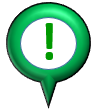 **ATTENTION: ** The Derivation for our Finite Difference EXPLICIT stencil is in the file [`bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx`](matlab:  edit bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx)

# Firstly confirm the Analytical solution

syms x t U(x,t) A B P pi

assume( (P-1)/2, 'integer'); % P is an ODD integer

The Analytical solution is:

U(x,t) =   A*exp(       -pi^2 *t/4)*sin(  pi*x/2)  + ...
           B*exp( -P^2 * pi^2 *t/4)*sin(P*pi*x/2)  + ...
           x 

$$U(x, t) = x+A\,{\mathrm{e}}^{-\frac{\pi^{2}\,t}{4}}\,\sin\left(\frac{\pi \,x}{2}\right)+B\,\sin\left(\frac{P\,\pi \,x}{2}\right)\,{\mathrm{e}}^{-\frac{P^{2}\,\pi^{2}\,t}{4}}$$

Compute ${U_T \;=\;U}_{\textrm{XX}}$   .... and we're expecting that ${{0\;=\;U}_T -\;U}_{\textrm{XX}}$

U_T  = diff(U,t);
U_XX = diff(U,x,2);
U_T - U_XX

$$ans(x, t) = 0$$

** Check Initial Conditions:**

- $U\left(x,0\right)\;=\;f\left(x\right)$    for    $\left(0\le x\le 1\right)$

U(x,0)

$$ans = x+A\,\sin\left(\frac{\pi \,x}{2}\right)+B\,\sin\left(\frac{P\,\pi \,x}{2}\right)$$

 **Check Boundary Conditions:**

- $\begin{array}{l}
U\left(0,t\right)\;=0\\
U_X \left(1,t\right)=1
\end{array}$    for $\left(t\;>\;0\right)$

U(0,t)

$$ans = 0$$

U_X(x,t) = diff(U,x);
U_X(1,t)

$$ans = \frac{A\,\pi \,\cos\left(\frac{\pi }{2}\right)\,{\mathrm{e}}^{-\frac{\pi^{2}\,t}{4}}}{2}+\frac{B\,P\,\pi \,{\mathrm{e}}^{-\frac{P^{2}\,\pi^{2}\,t}{4}}\,\cos\left(\frac{P\,\pi }{2}\right)}{2}+1$$

Given that we have enforced the condition that ***P is an ODD integer***, then simplifying the above expression shouldn't be a surprise:

tmp_U_X = U_X;
tmp_U_X = subs(tmp_U_X, x, 1);
tmp_U_X = subs(tmp_U_X, [cos(P*pi/2), cos(pi/2)],[ 0,0]);
simplify(tmp_U_X(1,t))

$$ans = 1$$

And we can visualize the analytic solution too:

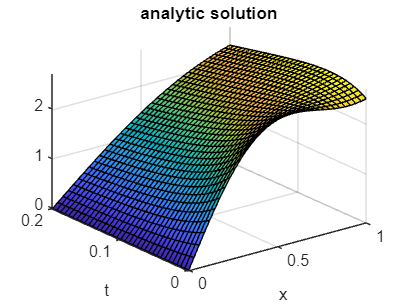

[tmp_A,tmp_B,tmp_P] = LOC_get_ABP();

tmp_U = subs(U, [A,B,P,pi], [tmp_A,tmp_B,tmp_P,3.141592653589793]);

figure;
   fsurf(tmp_U, [0,1,  0, 0.2]);
   xlabel('x'); ylabel('t'); title('analytic solution')

# Clear the Workspace

OK.  Clear the Symbolic variables

% clear all
clear variables  % R2021b

# Implement the FTCS technique

Now let's Numerically solve this problem using the **Forward Time Central Space** (FTCS) technique.

 **ATTENTION: ** ****** STENCIL DERIVATION ******

- The Derivation for our Finite Difference IMPLICIT stencil is in the file [`bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx`](matlab:  edit bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx)

## Setup the grid inputs

grid_T.NUM_X_INTERVALS =  50;
grid_T.NUM_T_INTERVALS = 3000;

Specify:    $r=\frac{\Delta t}{{\left(\Delta x\right)}^2 }$

grid_T.r               =  0.07; 
grid_T = LOC_calc_grid_params(grid_T)

grid_T = struct with fields:
    NUM_X_INTERVALS: 50
    NUM_T_INTERVALS: 3000
                  r: 0.0700
        NUM_X_NODES: 51
            x_nodes: [0 0.0200 0.0400 0.0600 0.0800 0.1000 0.1200 0.1400 0.1600 0.1800 0.2000 0.2200 0.2400 0.2600 0.2800 0.3000 0.3200 0.3400 0.3600 0.3800 0.4000 0.4200 0.4400 0.4600 0.4800 0.5000 0.5200 0.5400 0.5600 0.5800 0.6000 0.6200 0.6400 … ]
                 dx: 0.0200
                 dt: 2.8000e-05
        NUM_T_NODES: 3001
            t_nodes: [0 2.8000e-05 5.6000e-05 8.4000e-05 1.1200e-04 1.4000e-04 1.6800e-04 1.9600e-04 2.2400e-04 2.5200e-04 2.8000e-04 3.0800e-04 3.3600e-04 3.6400e-04 3.9200e-04 4.2000e-04 4.4800e-04 4.7600e-04 5.0400e-04 5.3200e-04 5.6000e-04 … ]


## Prepare the Solution matrix - $U\left(\textrm{xi},\;\textrm{tj}\right)$

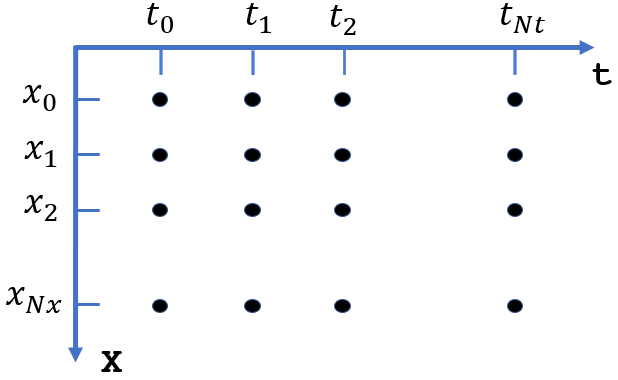

U = zeros(grid_T.NUM_X_NODES, grid_T.NUM_T_NODES );

## Assign the Initial Conditions

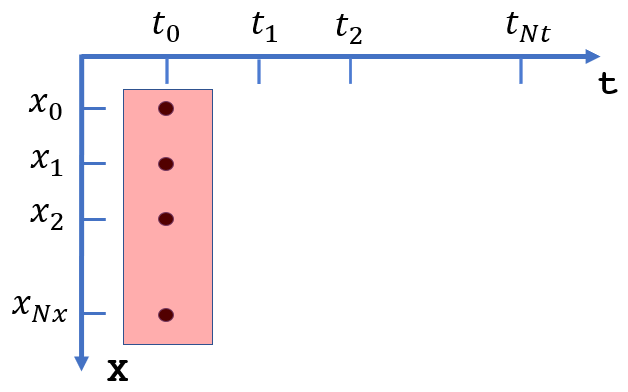

U(:,1) =  LOC_ICs(grid_T);

## Perform the time stepping Loop

for kk_t =2:grid_T.NUM_T_NODES
    
    U_at_t_prev = U(:,kk_t-1);
    
    U_at_t      = LOC_step(grid_T, U_at_t_prev);    

    U(:,kk_t)   = U_at_t;
end

## And plot the results

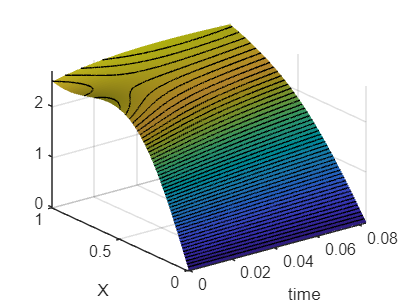

figure;
t = grid_T.t_nodes;
x = grid_T.x_nodes;

surf( t, x, U, 'EdgeColor',"none");  %, 'EdgeColor','k', 'MeshStyle','row');
    xlabel('time');   ylabel('X');
    camlight('headlight')
    axis("tight")
hold("on")
    contour3(gca,  t, x, U, 50, '-k') 

# Slice and Dice

Let's drag a "cutting" plane along the TIME axis and plot the temperature $U\left(x,\;t=\textrm{constant}\right)$

- 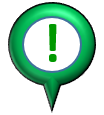 NOTE:  the slider bar represents "normalised time", i.e.: 

- $\Longrightarrow$` t_norm = 1`  , corresponds to $t=t_{\textrm{MAX}}$

- $\Longrightarrow$` t_norm = 0`  , corresponds to $t=t_{\textrm{MIN}}$

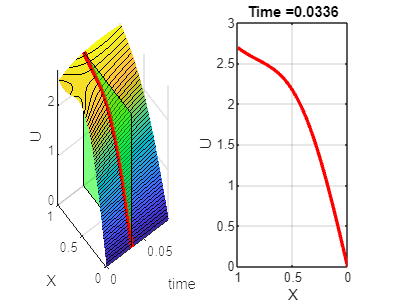

t_norm = 0.4;

LOC_slice_and_dice(U, grid_T, t_norm)

# Compare Numeric and Analytic Solution:

Compute the Analytical solution at the same grid points as the Numeric Solution:

U_an    = LOC_analytic_solution_mat(grid_T);
err_mat = abs(U_an - U);
err_mat = log10(err_mat);

And plot the error on a $\log_{10}$ scale.

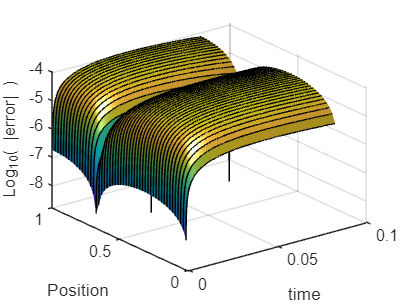

figure;
t = grid_T.t_nodes;
x = grid_T.x_nodes;

surf( t, x, err_mat, 'EdgeColor','k', 'MeshStyle','row');
xlabel('time'); ylabel('Position');  zlabel('Log_{10}( |error| )');
camlight('headlight')

# Local Subfunctions only beyond this point

**Compute GRID parameters**

function grid_T = LOC_calc_grid_params(grid_T)

    grid_T.NUM_X_NODES = 1 + grid_T.NUM_X_INTERVALS;
    grid_T.x_nodes     = linspace(0,1,grid_T.NUM_X_NODES);
    grid_T.dx          = grid_T.x_nodes(2) - grid_T.x_nodes(1);
    grid_T.dt          = grid_T.r * (grid_T.dx )^2;
    grid_T.NUM_T_NODES = 1 + grid_T.NUM_T_INTERVALS;    
    grid_T.t_nodes     = grid_T.dt * [0:(grid_T.NUM_T_NODES-1)];
    
end

**Get A,B,P:**

function [A,B,P] = LOC_get_ABP()
    A       = 2.2;
    B       = 0.7;
    P       = 3;    
end

**Initial Conditions**

function U_col = LOC_ICs(grid_T)

    [A,B,P] = LOC_get_ABP();
    
    x_nodes = grid_T.x_nodes(:);    
    U_col   = A*sin(pi*x_nodes/2) + B*sin(P*pi*x_nodes/2) + x_nodes;

end

**Compute solution at **$t_{j+1}$** given that we already know the solution at **$t_j$

function U_jp1 = LOC_step(grid_T, U_j)

   r        = grid_T.r;
   dx       = grid_T.dx;
   
   U_jp1    = zeros(grid_T.NUM_X_NODES, 1);
   U_jp1(1) = LOC_LEFT_boundary_point();

   for ii_x=2:(grid_T.NUM_X_NODES-1)
      U_jp1(ii_x) =  LOC_internal_grid_point_stencil(U_j,r,ii_x);       
   end
   
   U_jp1(end) = LOC_RIGHT_boundary_point(U_j, r, dx);
end

**AN internal grid point:**

 **ATTENTION: ** The Derivation for our Finite Difference EXPLICIT stencil is in the file [`bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx`](matlab:  edit bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx)

function U_i_jp1 = LOC_internal_grid_point_stencil(Uj,r,i)
         U_i_jp1 =   r*Uj(i-1) + (1-2*r)*Uj(i) + r*Uj(i+1);
end

**LEFT Boundary Condition grid point**

function U_left = LOC_LEFT_boundary_point()
         U_left = 0;
end

**RIGHT Boundary Condition grid point**

 **ATTENTION: ** The Derivation for our Finite Difference EXPLICIT stencil is in the file [`bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx`](matlab:  edit bh_deriv_for_1d_pde_FTCS_trans_explicit.mlx)

function U_N_jp1 = LOC_RIGHT_boundary_point(Uj, r, dx)
   U_N_jp1 =   2*r*Uj(end-1) + (1-2*r)*Uj(end) + 2*r*dx;
end

**Analytical solution:**

function U = LOC_analytic_sol(x,t)

    [A,B,P] = LOC_get_ABP();
    
    U = A*exp(       -pi^2 *t/4)*sin(  pi*x/2)  + ...
        B*exp( -P^2 * pi^2 *t/4)*sin(P*pi*x/2)  + ...
        x; 
end

**Analytical solution - MATRIX**

function U = LOC_analytic_solution_mat(grid_T)

   U      = zeros(grid_T.NUM_X_NODES, grid_T.NUM_T_NODES );
   U(:,1) =  LOC_ICs(grid_T);
   
    for jj_t =2:grid_T.NUM_T_NODES
       t = grid_T.t_nodes(jj_t);
       for ii_x =1:grid_T.NUM_X_NODES
            x = grid_T.x_nodes(ii_x);           
           
            U(ii_x, jj_t) = LOC_analytic_sol(x,t);
           
       end % x
    end       % t    
end

**Slice and Dice:**

function LOC_slice_and_dice(U, grid_T, t_norm)

    kk_t   = 1 +  round(t_norm*(-1+length(grid_T.t_nodes)));

    t_val = grid_T.t_nodes(kk_t);   
    U_vec = U(:, kk_t);
    x_vec = grid_T.x_nodes(:);
      
    % set up figure and teh 2 axes
    figure;
    hax(1) = subplot(1,2,1);
    hax(2) = subplot(1,2,2);
   
    % plot the U vs X slice
    plot(hax(2), x_vec, U_vec, '-r', 'LineWidth', 2);
    grid(hax(2), 'on');
    xlabel(hax(2),'X'); ylabel(hax(2),'U');
    set(hax(2), 'XDir', 'reverse');
    title(hax(2), ("Time =" + t_val))
    
    
    % plot the 3D surface
    t = grid_T.t_nodes;
    x = grid_T.x_nodes;
    hAX = hax(1);
    surf(hAX, t,  x, U, 'EdgeColor','none');
    %surf(hAX, t,  x, U, 'EdgeColor','k', 'MeshStyle','row');
        xlabel(hAX,'time');
        ylabel(hAX, 'X');
        zlabel(hAX, 'U');
        %lightangle(75, 70)
        hold(hAX,'on');
        contour3(hAX,  t, x, U, 50, '-k') 
       
    % plot the slice plane
    xp = [t_val, t_val, t_val, t_val ];
    yp = [x_vec(1), x_vec(end), x_vec(end), x_vec(1) ];
    zp = [0,0,max(U_vec), max(U_vec)];
    patch(hAX, xp,yp,zp, 'g', 'FaceAlpha', 0.5);
    
    t_vec = t_val*ones(size(x_vec));
    plot3(hAX,t_vec,x_vec,U_vec, '-r', 'LineWidth',3)
end